% IMPORTANTE DAR VALORES DE LOS PARAMETROS CERCANOS A LA SALIDA DESEADA

% https://controlautomaticoeducacion.com/analisis-de-sistemas/modelo-de-motor-dc/
% https://ctms.engin.umich.edu/CTMS/index.php?example=MotorSpeed&section=SystemModeling

% Limpiando el workspace
clear
close

% Cargamos los datos de los experimentos
% 1  [1x1 Signal]      mot_int     Intensidad A         
% 2  [1x1 Signal]      mot_volt    Voltaje    V nominal  
% 3  [1x1 Signal]      mot_counts  Velocidad  rad/s        
% 4  [1x1 Signal]      mot_input   PWM Entrada
load('Experiment_identification.mat')

% Motor Parameters
% J = 0.001;
% b = 0.01;
% K = 0.1;
% R = 1.3; % Medido con el multimetro
% L = 0.01;

J = 1.1378e-05; % 1.1378e-05 a 1.3654e-05
b = 1.3760e-05;
K = 0.0172;
L = 0.0015;
R = 1.3; % Medido con el multimetro

b/J

ans = 1.2094

K/J

ans = 1.5117e+03


K/L

ans = 11.4667

R/L

ans = 866.6667

1/L

ans = 666.6667

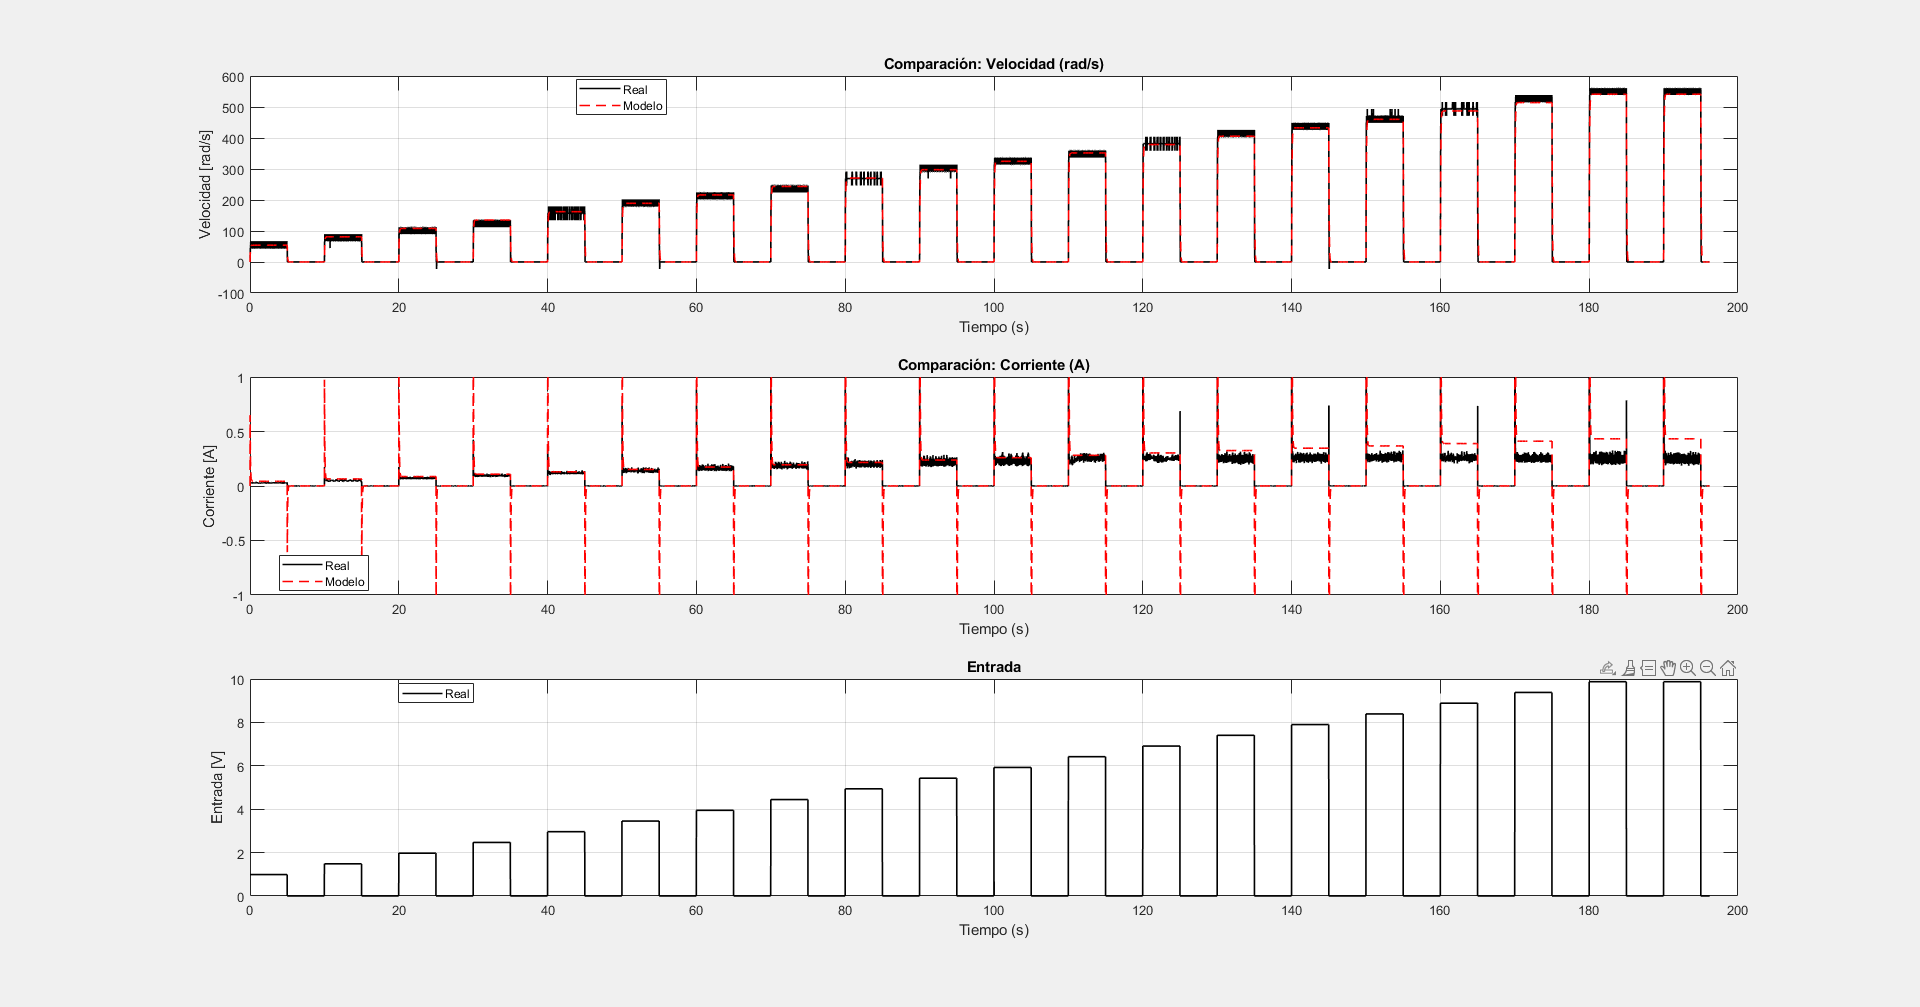


% Empezamos los experimentos a partir del índice

% Media de los voltajes de la batería medido
V_nom = mean(data{2}.Values.Data);

% También vamos a remover la corriente mínima que consume el driver con el
% valor mínimo que da el experimento en los primeros valores
% se asume similar en todos los experimentos
I_offset = 0.016; % Current [A] 

% El valor aplicado al driver va desde 0-255, por tanto, diviremos U entre
% U_max para normalizarlo a 1 y luego multiplicaremos por V_nom, para
% estimar el voltaje aplicado al motor.
U_max = 255;

% Periodo de muestreo
DT = 0.01; % segundos [s] 1/100

% Experimentos steps
U = (squeeze(data{4}.Values.Data)/U_max) * V_nom;
V = double(squeeze(data{3}.Values.Data)); % Velocity [rad/s]
I = squeeze(data{1}.Values.Data) - I_offset; % Current [A]

identification_iddata = iddata([V I], U, DT);

% Ya estamos preparados para la identificación
% https://www.mathworks.com/help/ident/ug/how-to-estimate-state-space-models-at-the-command-line.html

A = [-b/J K/J; -K/L -R/L]; % Correspoderan a m1, m2, m3, m4
B = [0; 1/L]; % Correspondera a m5
C = eye(2);
D = 0;
sys = idss(A, B, C, D, 'Ts', 0);

% S = sys.Structure;
% S.B.Free(1) = false;
% S.C.Free = false;
% S.D.Free = false;
% S.K.Free = false;
% sys.Structure = S;
% 
% opt = ssestOptions;
% opt.InitialState = 'zero';
% 
% msys = ssest(identification_iddata, sys, opt);
% 
% msys

% --- Simulación del modelo identificado con lsim ---
t = (0:length(U)-1)' * DT;  % Vector de tiempo

% Simulamos la respuesta del sistema con la entrada real U
% [Y_sim, ~, ~] = lsim(msys, U, t);
[Y_sim, ~, ~] = lsim(sys, U, t);

% --- Graficamos la comparación de la salida simulada vs real ---

figure;
set(gcf,'Visible','on')
set(gcf, 'Position', get(0, 'Screensize'));

subplot(3,1,1)
plot(t, V, 'k', 'LineWidth', 1.2); hold on;
plot(t, Y_sim(:,1), 'r--', 'LineWidth', 1.2);
title('Comparación: Velocidad (rad/s)');
legend('Real', 'Modelo', 'Location','best');
xlabel('Tiempo (s)');
ylabel('Velocidad [rad/s]');
grid on;

subplot(3,1,2)
plot(t, I, 'k', 'LineWidth', 1.2); hold on;
plot(t, Y_sim(:,2), 'r--', 'LineWidth', 1.2);
title('Comparación: Corriente (A)');
legend('Real', 'Modelo', 'Location','best');
xlabel('Tiempo (s)');
ylabel('Corriente [A]');
grid on;
ylim([-1 1])

subplot(3,1,3)
plot(t, U, 'k', 'LineWidth', 1.2); hold on;
title('Entrada');
legend('Real', 'Location','best');
xlabel('Tiempo (s)');
ylabel('Entrada [V]');
grid on;